%%                 - Autonomous USV Path Planning Algorithm -                  %%
%    This code uses an algorithm based on the projection collision avoidance    %
%      method to find a path from the start point to the target point           %
%     Every obstacle is avoided using all the permutations of obstacle array    %
%                                                                               %
%                Written by Dimitrios Stergianelis on August 2018               %
%                                                                               %
%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%
 
% Clean the workspace and close the open figures
clear
clc
close all
tic;
 
%% Parameters - Setting up the problem
 
% Start point S (XS, YS)
XS = 5;
YS = 2;
 
% Target point T (XT, YT)
XT = 36;
YT = 30;
 
% Obstacle representation: circle with centre at (XO, YO) and radius RO
XO = [10, 19, 29];
YO = [9, 17, 24];
RO = [4, 6, 3];
 
% Safety radius RB
% Was set equal to the radius of the vessel region (RV), for the simulations
RB = 0.571;
 
% Number of obstacles N
N = length(XO);
 
% Calculate the length of the straight line from S to T
Lstr = sqrt((XT - XS)^2 + (YT - YS)^2);
 
allCombos =  perms(1:N);
disp(allCombos);

     3     2     1
     3     1     2
     2     3     1
     2     1     3
     1     3     2
     1     2     3



     1



     3     2     1



K


     3



K


     5



K


     7



Solution found. 7 line segments.


Trajectory length: 43.8703


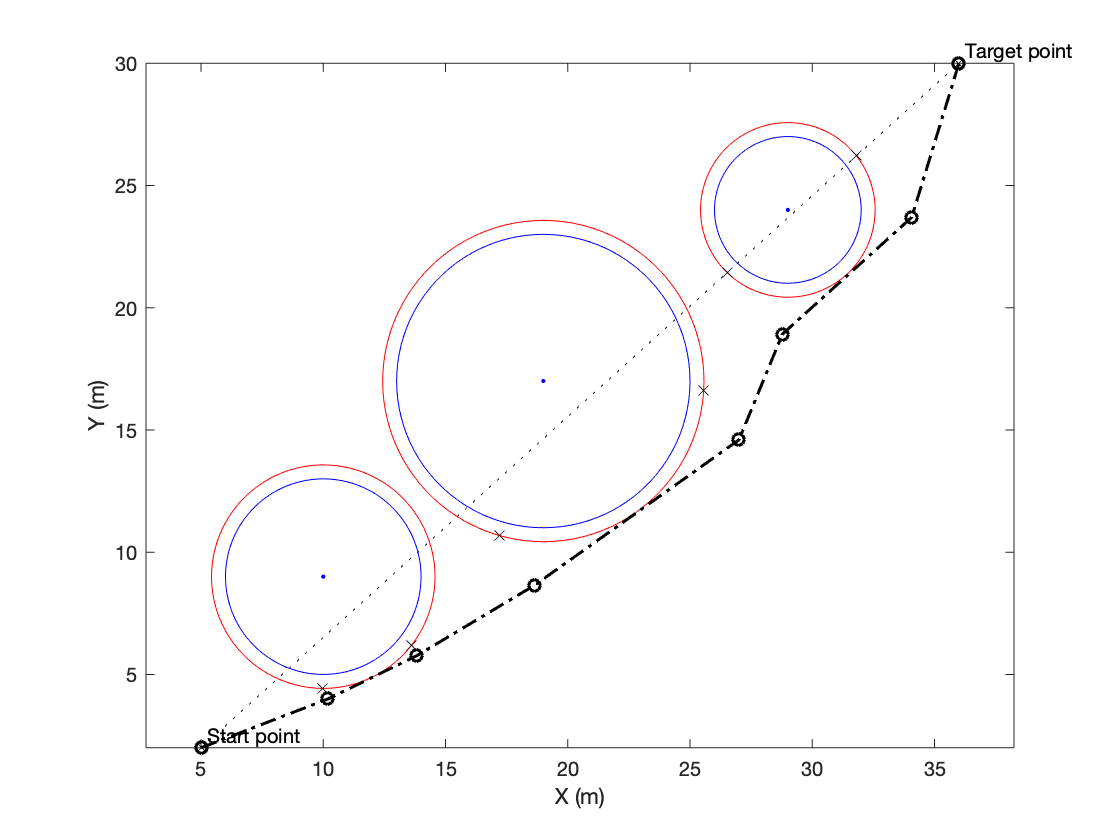

     2



     3     1     2



K


     3



K


     5



K


     7



Solution found. 7 line segments.


Trajectory length: 44.0955


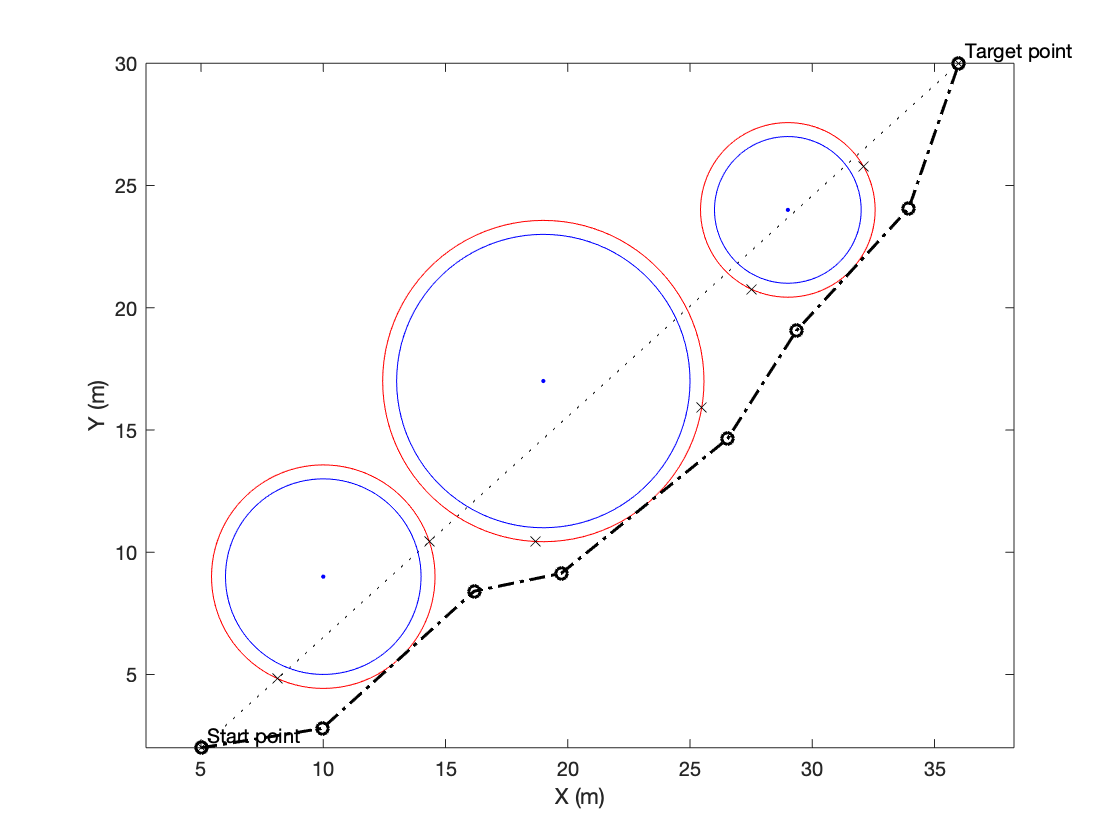

     3



     2     3     1



K


     3



K


     5



K


     7



Solution found. 7 line segments.


Trajectory length: 43.8703


     4



     2     1     3



K


     3



K


     5



K


     7



Solution found. 7 line segments.


Trajectory length: 43.3941


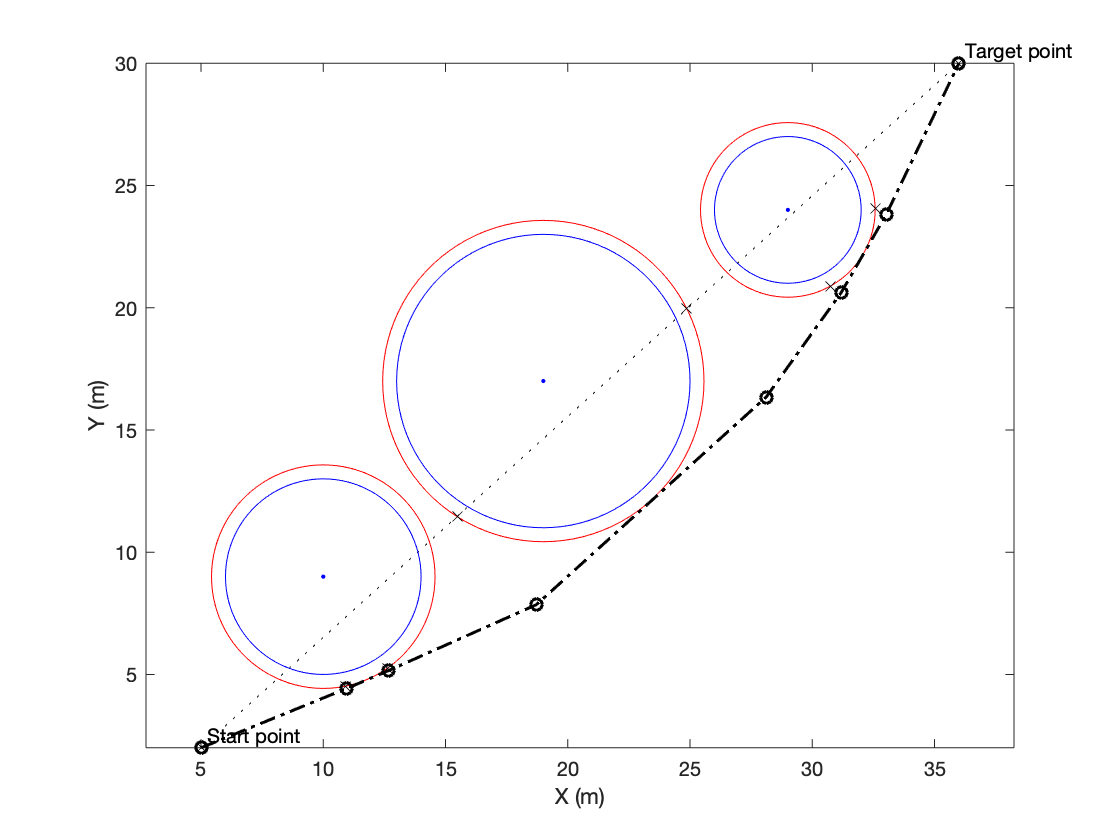

     5



     1     3     2



K


     3



K


     5



K


     7



Solution found. 7 line segments.


Trajectory length: 43.3941


     6



     1     2     3



K


     3



K


     5



K


     7



Solution found. 7 line segments.


Trajectory length: 43.3941


 
% Check if boat is already inside obstacle region
err = false;
for io = 1:N
    % Start point inside obstacle region
    check1 = (sqrt((XS - XO(io))^2 + (YS - YO(io))^2) < (RO(io) + RB));
    
    % Target point inside obstacle region
    check2 = (sqrt((XT - XO(io))^2 + (YT - YO(io))^2) < (RO(io) + RB));
    
    if (check1 || check2)
        fprintf("No solution. Start/Target point(s) inside obstacle region.\n");
        err = true;
        break
    end
end
 
if err
    return
end
 
% Exit this loop if a solution is found or if we have tested all combos
% Extra stop criterion should be added
i_attempt = 1;
solution_found = false;
previousTrajectoryLength = 0;
 
while (i_attempt <= length(allCombos))
    
    disp(i_attempt)
    figure(i_attempt);
    
    sort_idx = allCombos(i_attempt, :);
    disp(sort_idx);
    
    XO = XO(sort_idx);
    YO = YO(sort_idx);
    RO = RO(sort_idx);
    
    clf
    
    %% Plotting basic features
    [RD] = plot_obstacles(XS, YS, XT, YT, XO, YO, RO, RB, N);
    
    %% Core calculations
    
    % Initial path from S to T
    Px = [XS, XT];
    Py = [YS, YT];
    
    % Loop while there are line segments to be resolved
    % Initialize loop
    k = 1; % Number of line segments
    K = 1; % Number of lines
    
    while k <= K
        for n = 1:N % Loop for number of obstacles
            beginAgain = false;
            % Check if manoeuvre is needed
            % Inputs are, path segment start P(k) & end P(k+1), obstacle and boat settings
            % Outputs are the extra points due to the manoeuvre or empty if manoeuvre not needed
            [Xa, Ya, Xb, Yb, err] = vessel_find_path(Px(k), Py(k), Px(k+1), Py(k+1), XO(n), YO(n), RO(n), RB, XO, YO, RO);
            
            if (err)
                warning('Route point(s) inside obstacle region.')
                break
            end
            
            % Case that manoeuvre is needed
            if ~isempty(Xa)
                
                % Add extra points in path due to manoeuvre
                Px = [Px(1:k), Xa, Xb, Px(k+1:end)];
                Py = [Py(1:k), Ya, Yb, Py(k+1:end)];
                
                beginAgain = true;
                % Add number of new segments in the total counter
                K = K + 2;
                disp('K');
                disp(K);
                break
            end
        end
        
        % Move to next segment
        if (beginAgain)
            k = 1;
        else
            k = k + 1;
        end
        
        % Check if destination was reached or path too complex
        if (k > K)
            break
        end
    end
    
    %% Check if any point in path is within an obstacle area
    current_solution_found = true;
    err = false;
    
    % Loop for all points (except starting, ending where there is nothing to do)
    for k = (2:length(Px) - 1)
        
        % Loop for all obstacles
        for m = (1:length(XO))
            
            % Check if within radius
            if (sqrt((Px(k) - XO(m))^2 + (Py(k) - YO(m))^2) < RD(m))
                
                warning('Solution invalid! Trying again.')
                current_solution_found = false;
                
                % Increase counter to make sure we have not exhausted all permutations
                i_attempt = i_attempt + 1;
                
                % Indicate an error to exit second loop
                err = true;
                drawnow
                break
            end
        end
        
        % If this is an error, exit this loop as well
        if err
            break
        end
    end
    
    if current_solution_found
        %if at least one solution found, solution found
        solution_found = true;
        fprintf("Solution found. %d line segments.\n", K);
        
        % Find the length of each segment
        for is=1:K
            Ls(is) = sqrt((Px(is + 1) - Px(is))^2 + (Py(is + 1) - Py(is))^2);
        end
        
        % Find the total length
        TL = sum(Ls (1:K));
        
        if (previousTrajectoryLength == 0 || (TL < previousTrajectoryLength))
            prev_i_attempt = i_attempt;
            prev_sort_idx = sort_idx;
            previousTrajectoryLength = TL;
            K_min = K;
            Px_min = Px;
            Py_min = Py;
        end
        
        disp(['Trajectory length: ' num2str(TL)])
        plot(Px, Py, '-.ok', 'LineWidth', 1.5)
        % Increase counter to check the next combination
        % and continue to "while loop"
        i_attempt = i_attempt + 1;
        continue
    end
    
end

Finally


     4



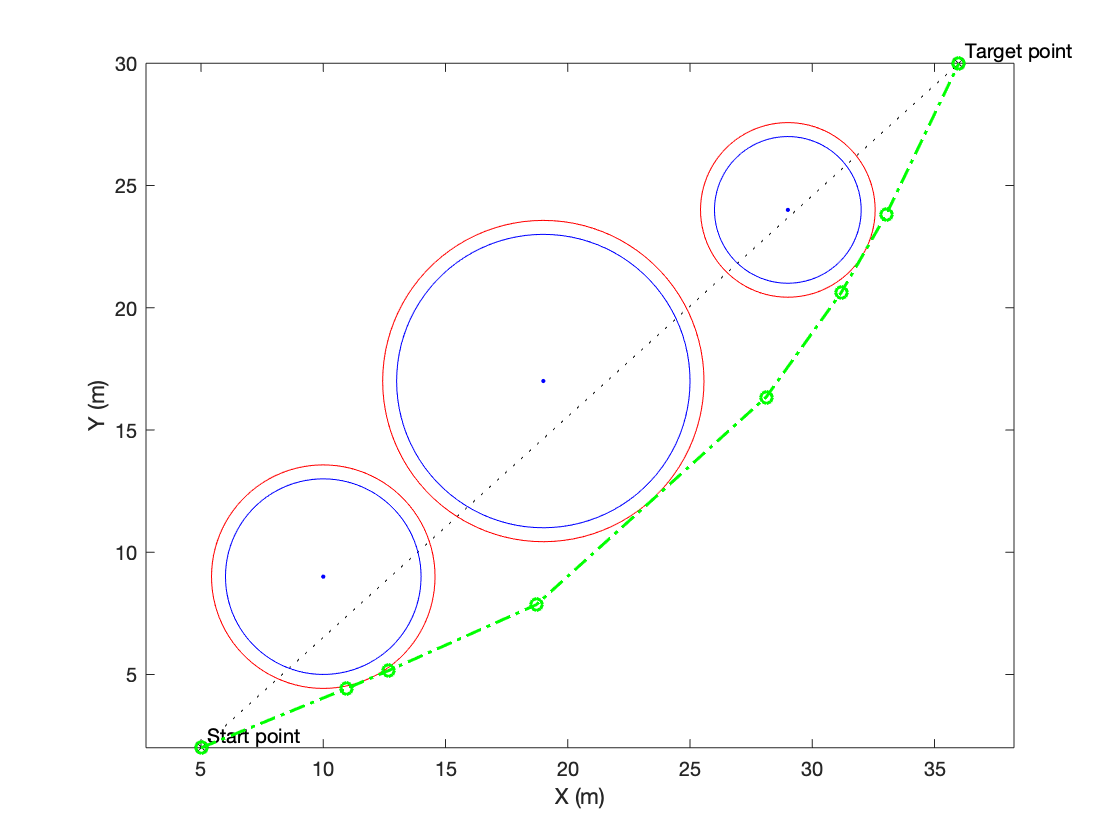

Simplification feasible.


i


     1



i


     2



i


     3



i


     4



i


     5



i


     6



K


     7



Straight-line Length: 41.7732


Minimum Trajectory No. of segments: 7


Minimum Trajectory Length: 43.3941


Simplified Trajectory No. of segments: 7


Simplified Trajectory Length: 43.3941


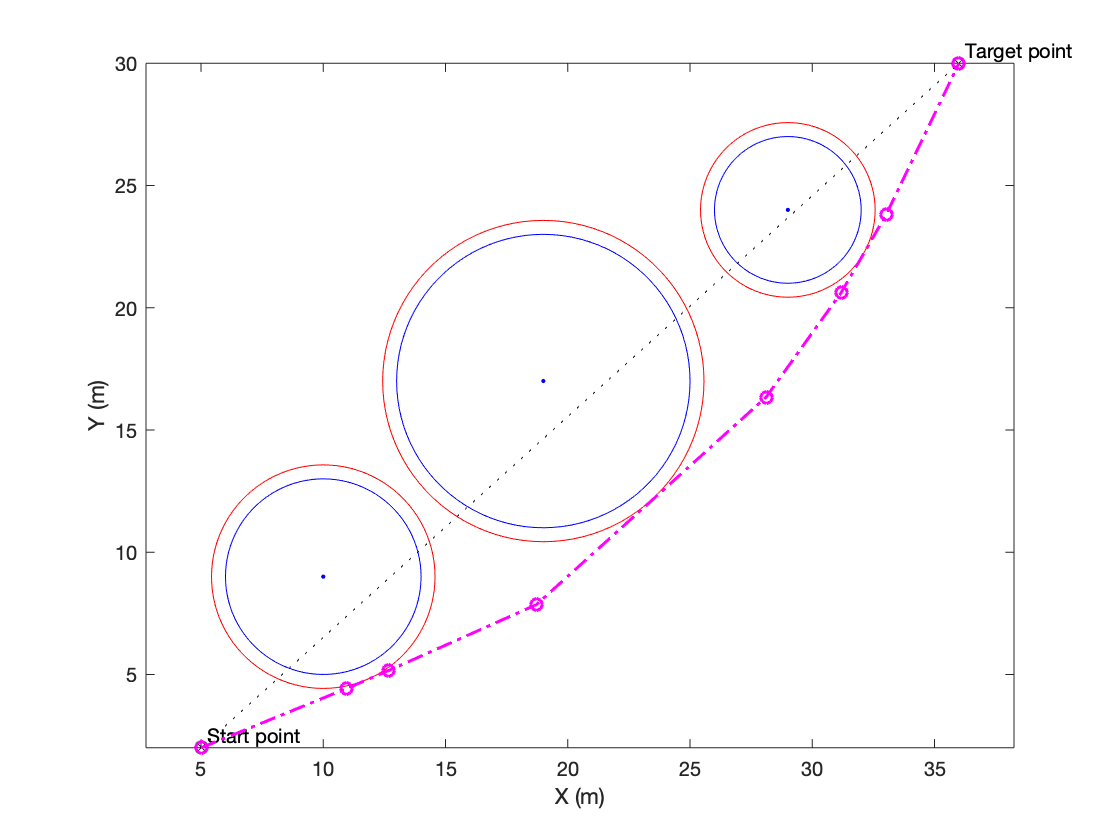

 
if solution_found
    disp('Finally');
    disp(prev_i_attempt);
    K_simple = K_min;
    figure(length(allCombos) + 1);
    
    %% Plotting basic features
    [RD] = plot_obstacles(XS, YS, XT, YT, XO, YO, RO, RB, N);
    plot(Px_min, Py_min, '-.og', 'LineWidth', 1.5)
    
    figure(length(allCombos) + 2);
    %% Plotting basic features
    [RD] = plot_obstacles(XS, YS, XT, YT, XO, YO, RO, RB, N);
    
    % check if any point is not needed
    atLeastOneSimplification = true;
    while atLeastOneSimplification
        disp('Simplification feasible.');
        atLeastOneSimplification = false;
        for i = 1:length(Px_min) -2
            disp('i');
            disp(i)
            
            for obstacle_no = 1:N
                [noIntersection, ferr] = check_intersection(Px_min(i), Py_min(i), Px_min(i+2), Py_min(i+2), XO(obstacle_no), YO(obstacle_no), RO(obstacle_no), RB);
                
                % if there is an intersection, exit for loop
                if ~noIntersection
                    break;
                end
            end
            
            if noIntersection
                disp('No Intersection');
                atLeastOneSimplification = true;
                Px_min(i+1) = [];
                Py_min(i+1) = [];
                K_simple = K_simple -1;
                break;
            end
        end
    end
    
    % Find the length of each segment
    disp('K')
    disp(K_simple)
    for is=1:K_simple
        Ls(is) = sqrt((Px_min(is + 1) - Px_min(is))^2 + (Py_min(is + 1) - Py_min(is))^2);
    end
    
    % Find the total length
    TL = sum(Ls (1:K_simple));
    
    disp(['Straight-line Length: ' num2str(Lstr)])
    fprintf('\n')
    disp(['Minimum Trajectory No. of segments: ' num2str(K_min)])
    disp(['Minimum Trajectory Length: ' num2str(previousTrajectoryLength)])
    fprintf('\n')
    
    disp(['Simplified Trajectory No. of segments: ' num2str(K_simple)])
    disp(['Simplified Trajectory Length: ' num2str(TL)])
    
    % Plot the simplified trajectory
    plot(Px_min, Py_min, '-.om', 'LineWidth', 1.5)
    
else
    fprintf("Error, algorithm did not converge.\n");
end

 
drawnow

toc

Elapsed time is 1.681051 seconds.
